# Fitting ellipse to data

For more detail see Apendix C of the book:

Robotics,Vision and Control of Peter Corke. Second edition 2017

## Generate randon points inside a ellipse

The general form of an ellipsoide is defined implicitly:

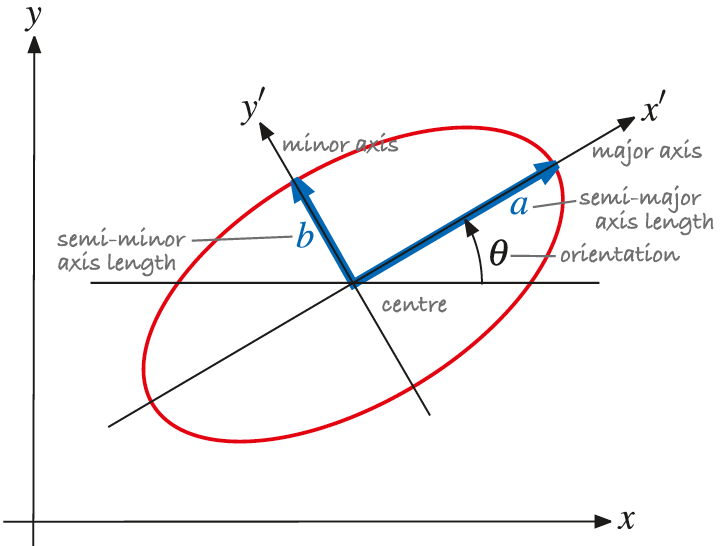


$$\frac{{{x^2}}}{{{a^2}}} + \frac{{{y^2}}}{{{b^2}}} = 1 \\
  \left( {\begin{array}{*{20}{c}}
  x&y 
\end{array}} \right)\left( {\begin{array}{*{20}{c}}
  {\frac{1}{{{a^2}}}}&0 \\ 
  0&{\frac{1}{{{b^2}}}} 
\end{array}} \right)\left( {\begin{array}{*{20}{c}}
  x \\ 
  y 
\end{array}} \right) = 1 \\
  {\left( {\begin{array}{*{20}{c}}
  x&y 
\end{array}} \right)^T}{\left( {\begin{array}{*{20}{c}}
  {{a^2}}&0 \\ 
  0&{{b^2}} 
\end{array}} \right)^{ - 1}}\left( {\begin{array}{*{20}{c}}
  x \\ 
  y 
\end{array}} \right) = 1 \\
  {{\mathbf{x}}^T}{{\mathbf{E}}^{ - 1}}{\mathbf{x}} = 1 \\ $$



$$\[\det ({\mathbf{E}})\left\{ {\begin{array}{*{20}{c}}
  { > 0 \to Ellipse} \\ 
  { = 0 \to Parabola} \\ 
  { < 0 \to Hiperbola} 
\end{array}} \right.\]$$


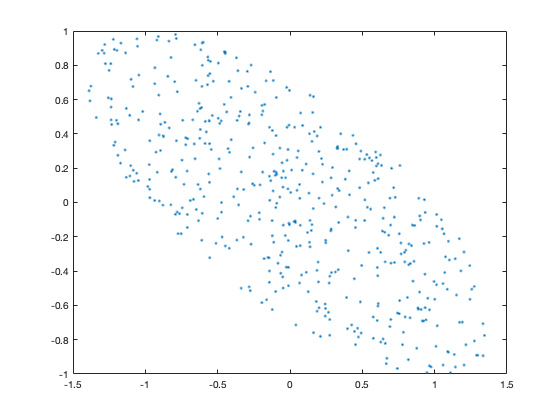

E = [2 -1; -1 1];
p=[];
while true
    x = (rand(2,1)-0.5)*4;
    if norm(x'*inv(E)*x) <= 1
        p = [p x];
    end
    if length(p) >= 500
        break;
    end
end
plot(p(1,:), p(2,:), '.')

## Compute the first moment 

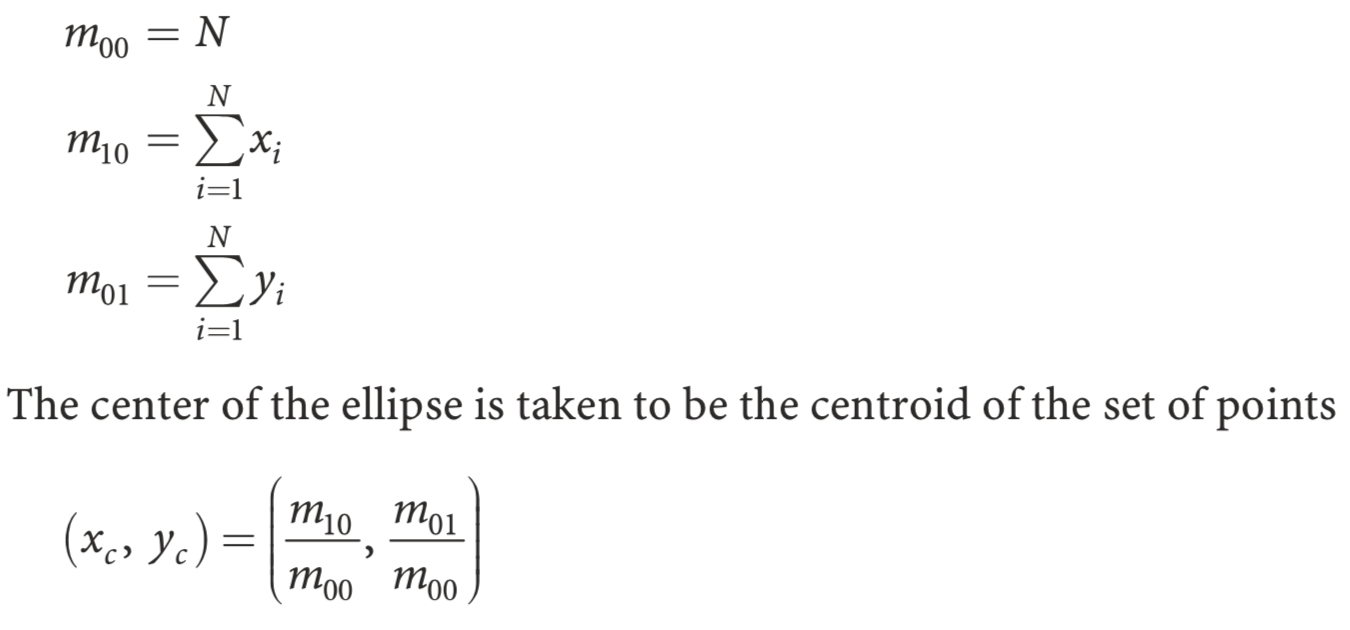

m00 = length(p)

m00 = 500

m10 = sum (p(1,:))

m10 = 18.8525

m01 = sum (p(2,:))

m01 = -13.7571

xc = m10/m00

xc = 0.0377

yc = m01/m00

yc = -0.0275

xc=mean(p(1,:))

xc = 0.0377

yc=mean(p(2,:))

yc = -0.0275

## Compute second moments relative to centroid

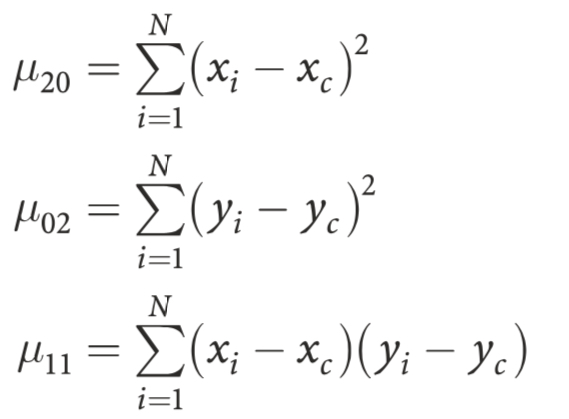

pp = bsxfun(@minus, p, [xc; yc])

pp =    -0.3894    0.5855    0.9826    0.7000    1.2826   -0.5167    0.6268    0.7002    0.7080   -0.0535   -0.2644    0.5656   -1.4403   -0.0918   -0.6892    0.3533    0.8265    0.9834   -0.4537    1.3237   -0.5680    0.4416   -0.8195    0.9646    1.2407    0.5740    0.8909   -1.2003   -0.7200   -1.2148   -0.6049    0.3707    0.3884   -1.2799   -0.8475   -1.4159    0.6304    0.0284   -1.0619   -1.0462    0.2151    0.1537    0.1716    0.4116    0.4508    0.1702   -0.3839    0.4511   -0.2904    0.3420
    0.5621    0.1217   -0.5769   -0.6002   -0.7731    0.5923   -0.6630    0.2088   -0.8426    0.1915    0.2288   -0.5658    0.8067   -0.3095    0.3726   -0.5627   -0.8187   -0.1528   -0.0074   -0.5170    0.6158    0.2630    0.0884   -0.0433   -0.9077   -0.8693   -0.5984    0.3301   -0.1870    0.3911   -0.0767   -0.4763   -0.0205    0.4684    0.4387    0.8613   -0.3539   -0.3427    0.0997    0.4637   -0.2254    0.2474   -0.7707   -0.1808   -0.5985    0.1689    0.2516   -0.8441    0.3432   -

mm = sum(pp.^2,2)

mm =   272.6410
  134.7843


m20= mm(1)

m20 = 272.6410

m02 =mm(2)

m02 = 134.7843

m11 = pp(1,:)*pp(2,:)'

m11 = -142.2595

## Inertia Matrix / Ellipse Matrix

J = [m20 m11; m11 m02]

J =   272.6410 -142.2595
 -142.2595  134.7843


E_est=4*J/m00

E_est =     2.1811   -1.1381
   -1.1381    1.0783


Plotting the ellipse 

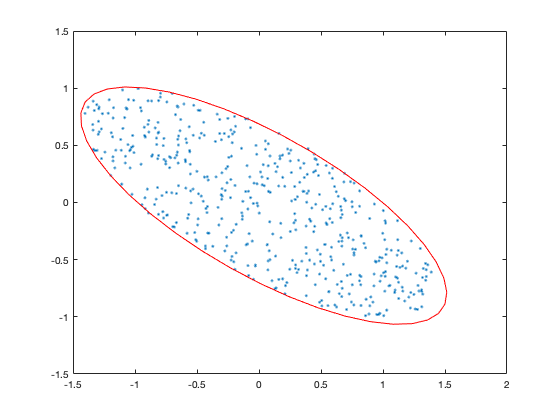

plot_ellipse(E_est, [xc yc],  'r');